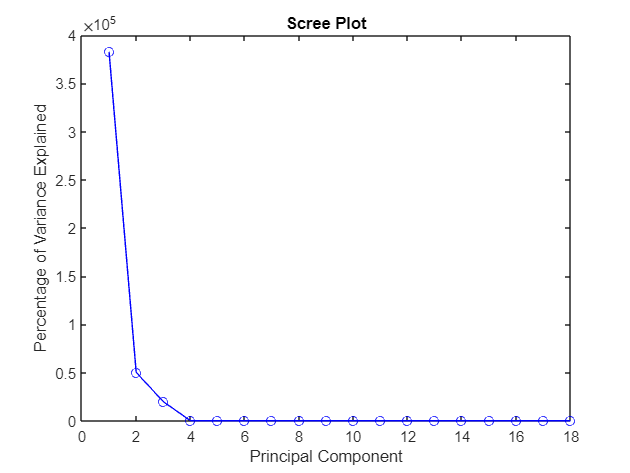

%cleaning workspace
clear;

% Load dataset
load Dataset_task2.mat;
%Dataset presenta dati mancanti o errati e colonna 19 duplicata di 18
short_matrix_no_id(:,19) = [];
short_matrix_no_id = fillmissing(short_matrix_no_id,"knn");

short_matrix_no_id(:,[2:4]) = normalize(short_matrix_no_id(:,[2:4]), 'range', [0, 1]);
short_matrix_no_id(:,[5,9:15,18]) = zscore(short_matrix_no_id(:,[5,9:15,18]));

[coefficients, scores, explained] = pca(short_matrix_no_id);

% Plot scree plot
plot(explained, 'bo-');
xlabel('Principal Component');
ylabel('Percentage of Variance Explained');
title('Scree Plot');

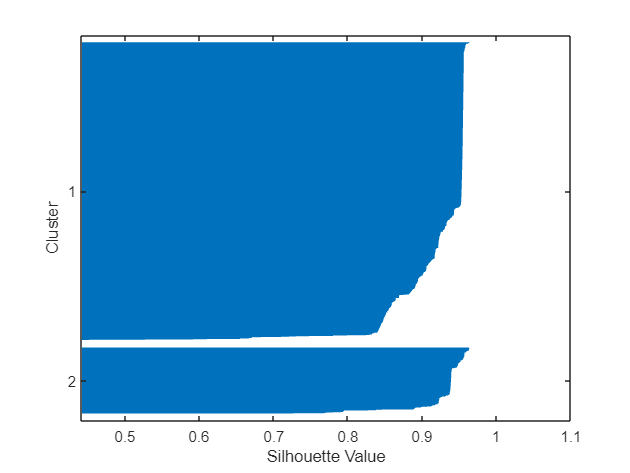

ans = 0.9256

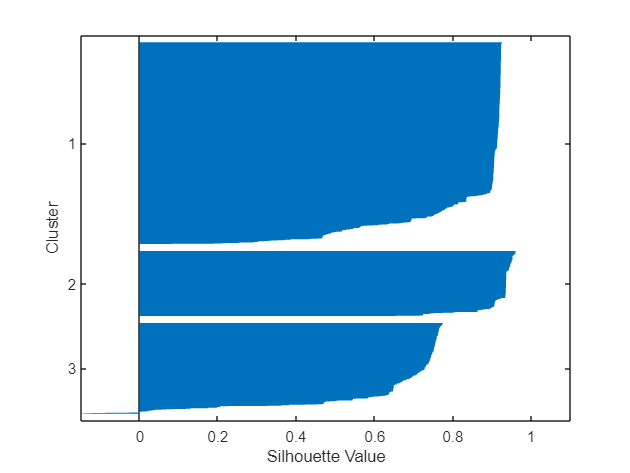

ans = 0.8097

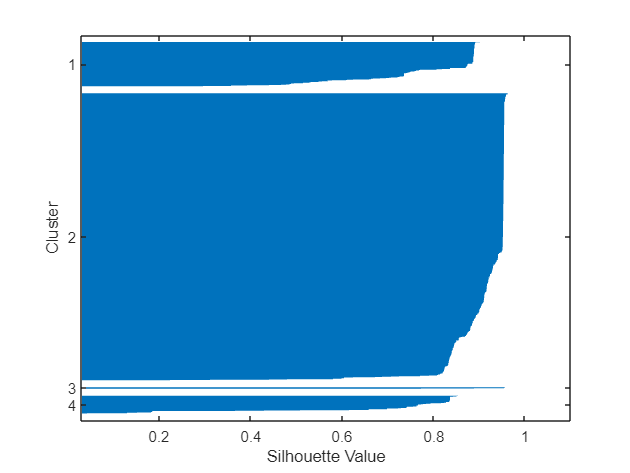

ans = 0.8901

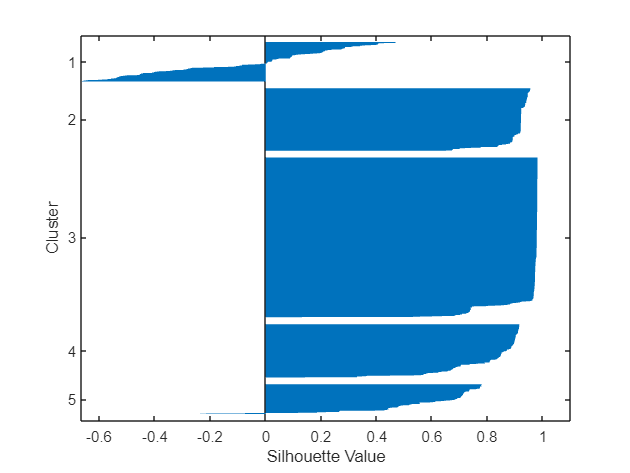

ans = 0.7756

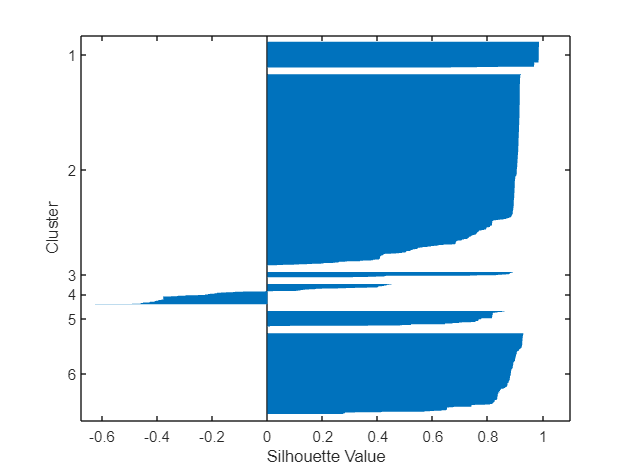

ans = 0.7850

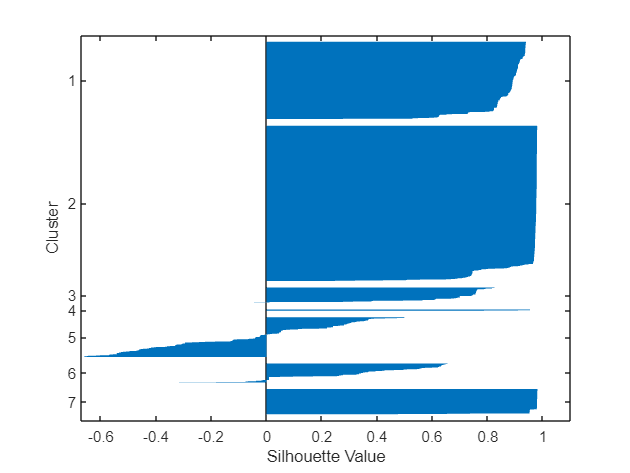

ans = 0.7600

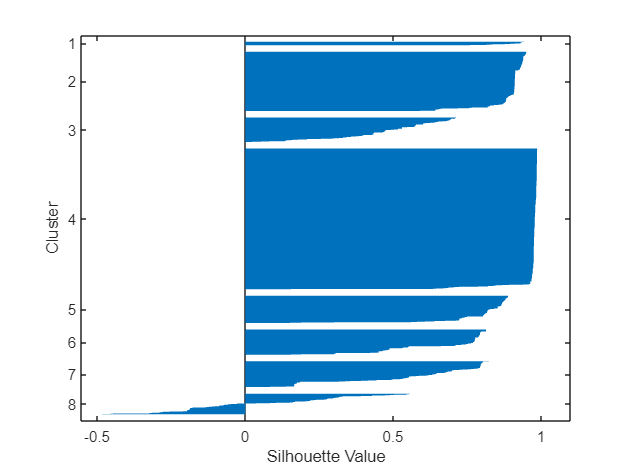

ans = 0.7919

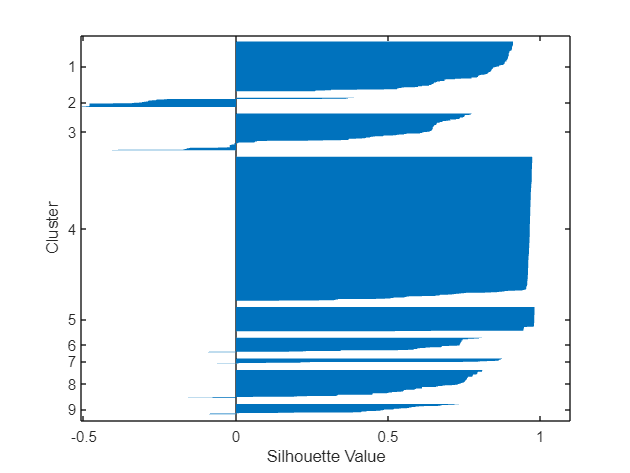

ans = 0.7676

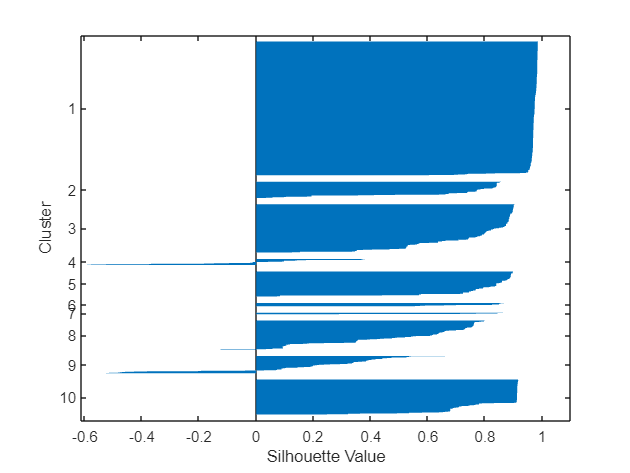

ans = 0.7847

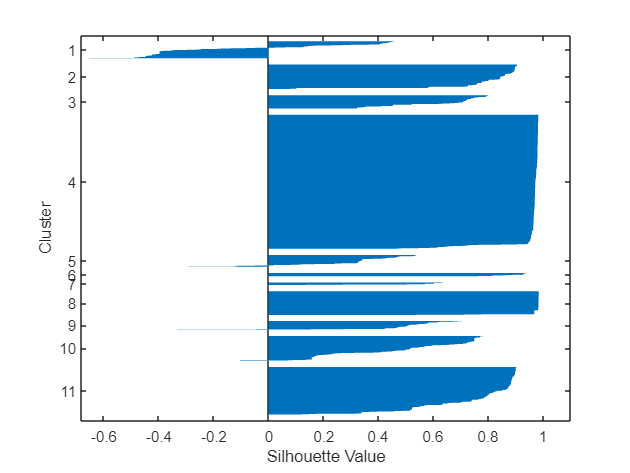

ans = 0.7639

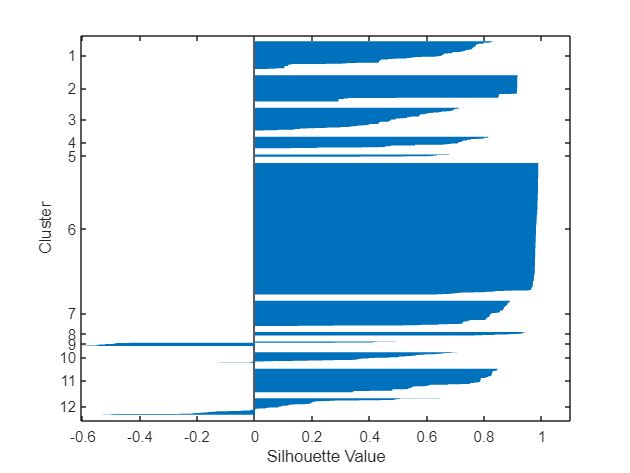

ans = 0.7469


%BUS LINE
bus_line = short_matrix_no_id(:,[1, 2:6, 8:9, 15, 16:17]);

%Vehicle ID
vehicle_id = short_matrix_no_id(:,[1, 6:8, 11:15, 18]);

%driver id
driver_id = short_matrix_no_id(:, [1, 6, 8, 15]);

% Calcolo del numero di cluster
unique_driver = unique(short_matrix_no_id(:,8),"rows"); %229 istanze
unique_vehicle = unique(short_matrix_no_id(:,6),"rows"); %105 istanze
unique_line = unique(short_matrix_no_id(:,1),"rows"); % 87 istanze


% Range of number of clusters
k_values = 2:12;

% Initialize array to store percentage variance for each matrix
variance_pct_driver = zeros(size(k_values));
variance_pct_vehicle = zeros(size(k_values));
variance_pct_busline = zeros(size(k_values));
mean_silhouette_scores = [];
% Perform k-means clustering for each number of clusters on driver_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on driver_id
    [idx_driver, centroids, sumd] = kmeans(driver_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_driver(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(driver_id,idx_driver);
    silhouette(driver_id,idx_driver);

    mean(sil_scores)
    
end

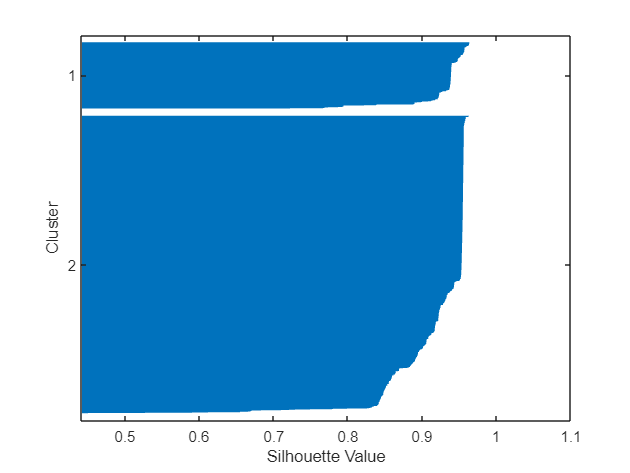

ans = 0.9256

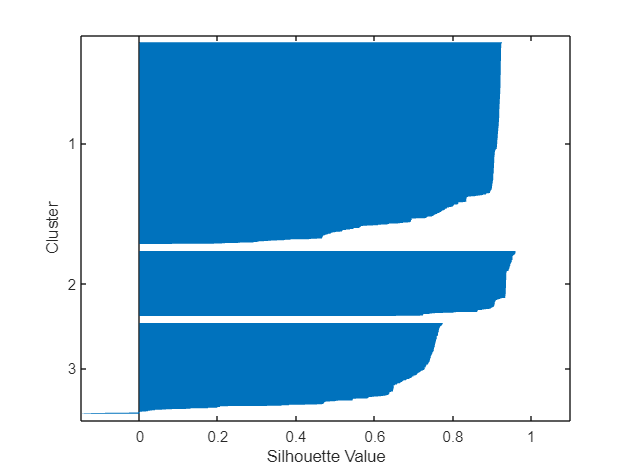

ans = 0.8097

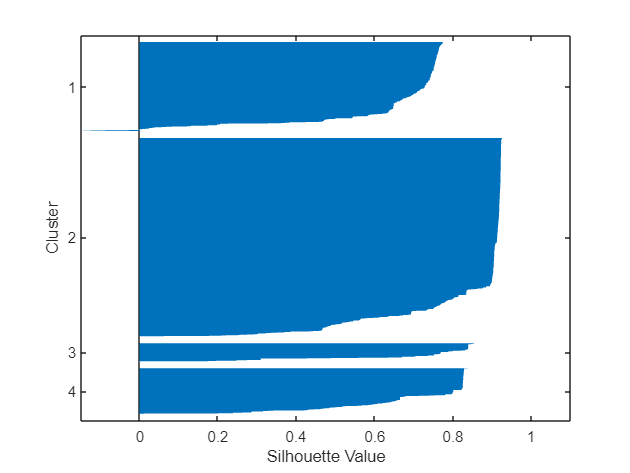

ans = 0.7702

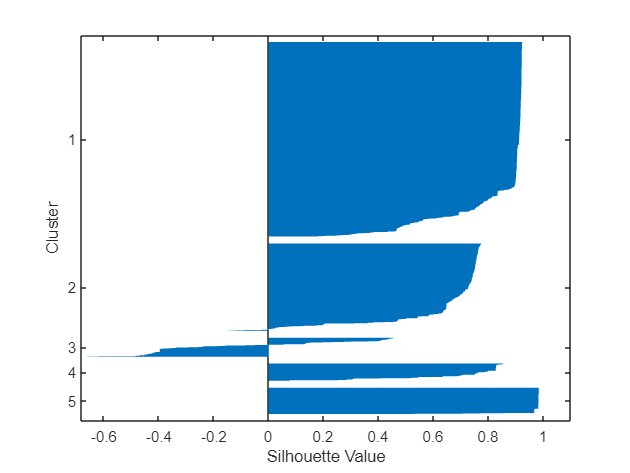

ans = 0.7447

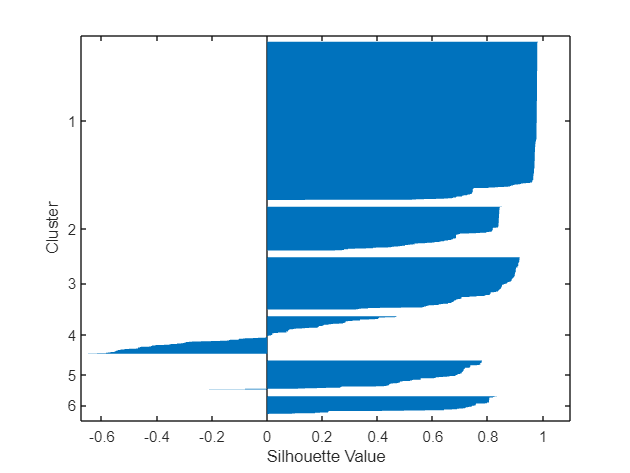

ans = 0.7424

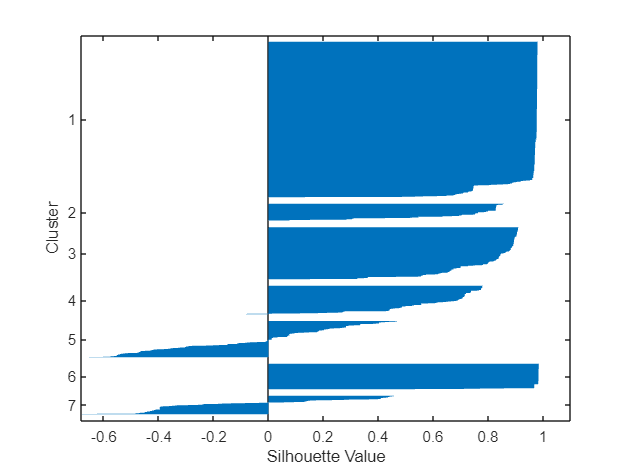

ans = 0.7167

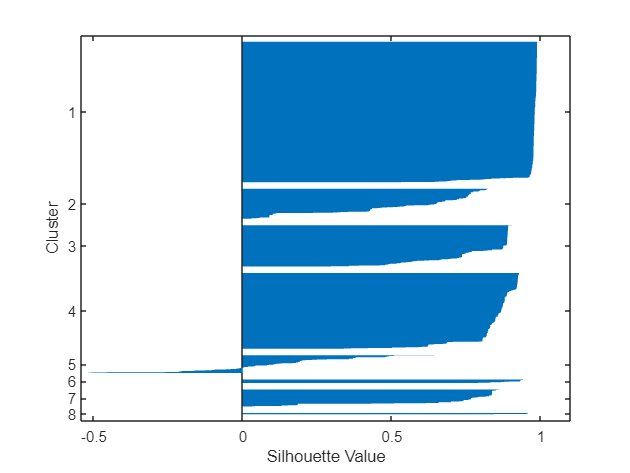

ans = 0.8165

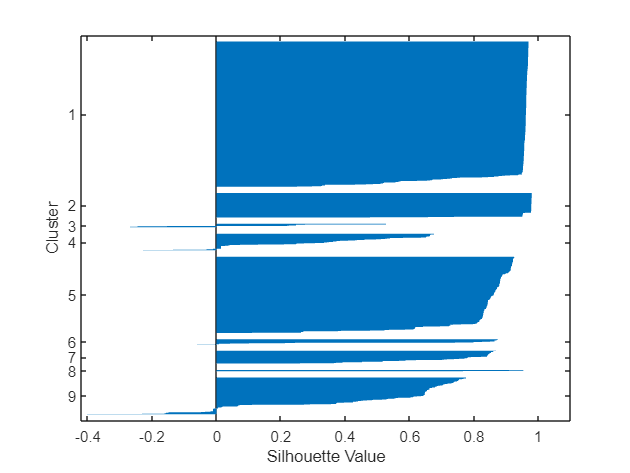

ans = 0.8026

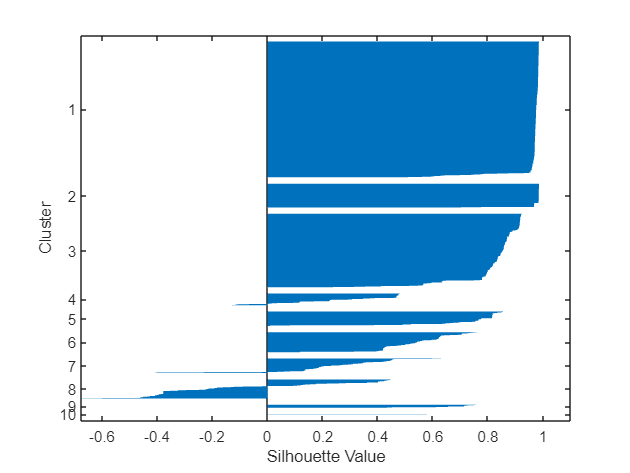

ans = 0.7689

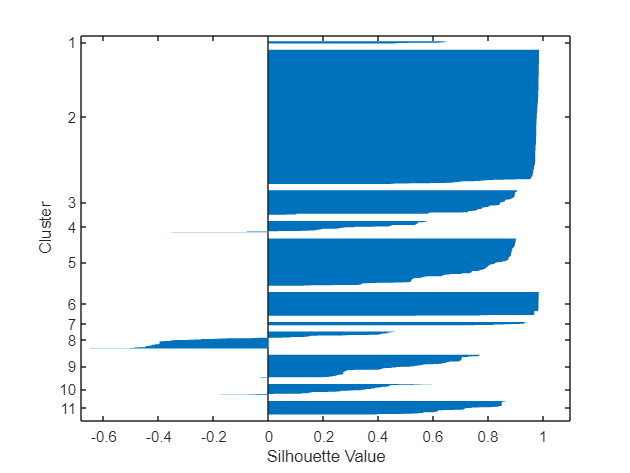

ans = 0.7683

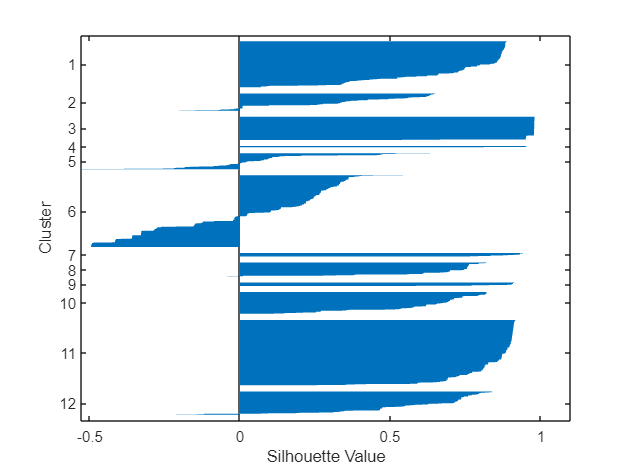

ans = 0.5238


% Perform k-means clustering for each number of clusters on vehicle_id
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on vehicle_id
    [idx_vehicle, centroids, sumd] = kmeans(vehicle_id, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_vehicle(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(vehicle_id,idx_vehicle);
    silhouette(vehicle_id,idx_vehicle);
    mean(sil_scores)
    
end

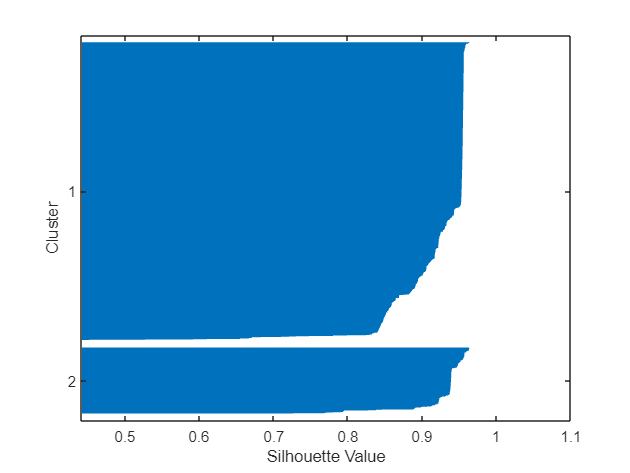

ans = 0.9256

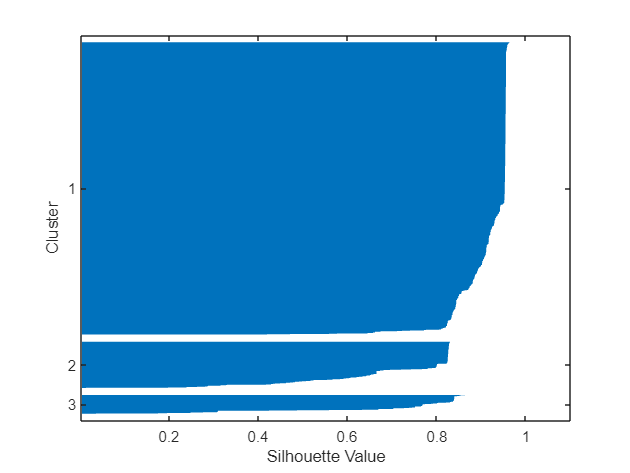

ans = 0.8810

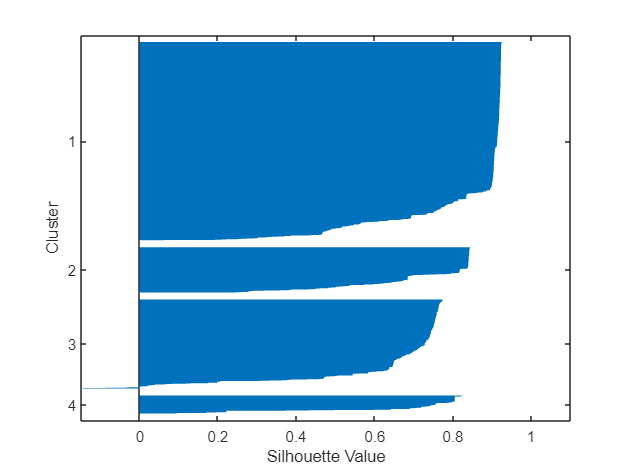

ans = 0.7707

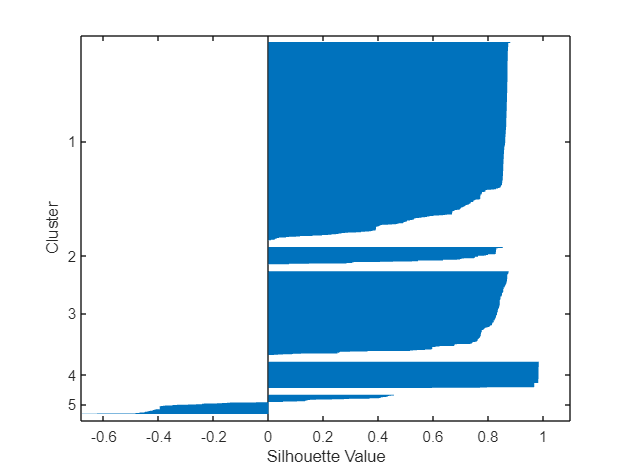

ans = 0.7425

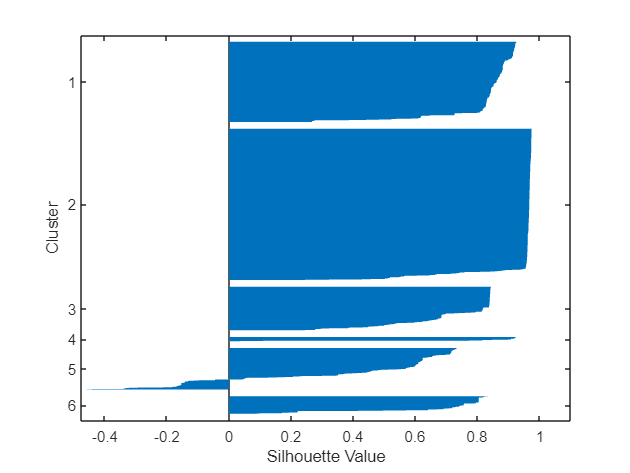

ans = 0.8019

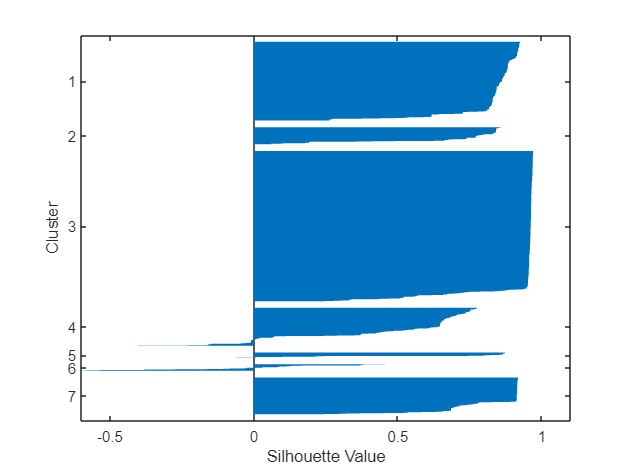

ans = 0.8063

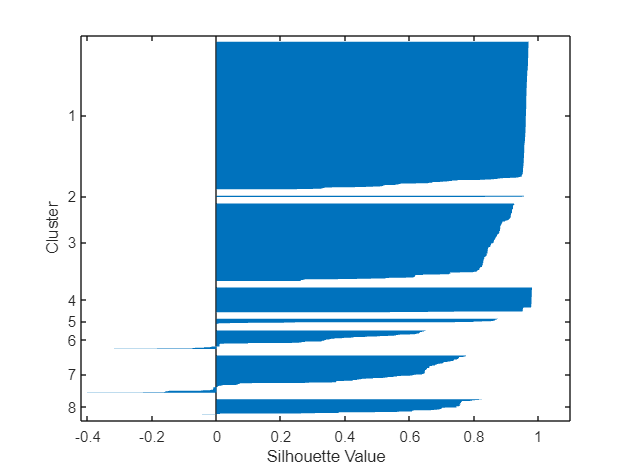

ans = 0.8040

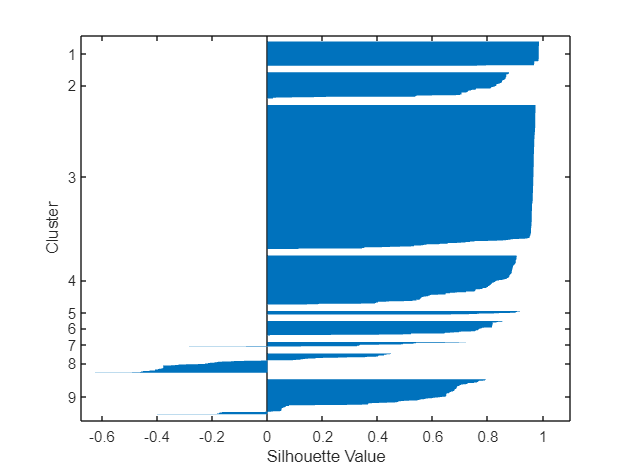

ans = 0.7657

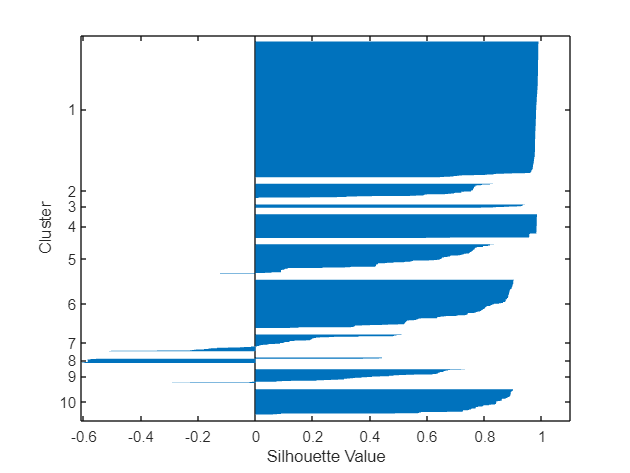

ans = 0.7749

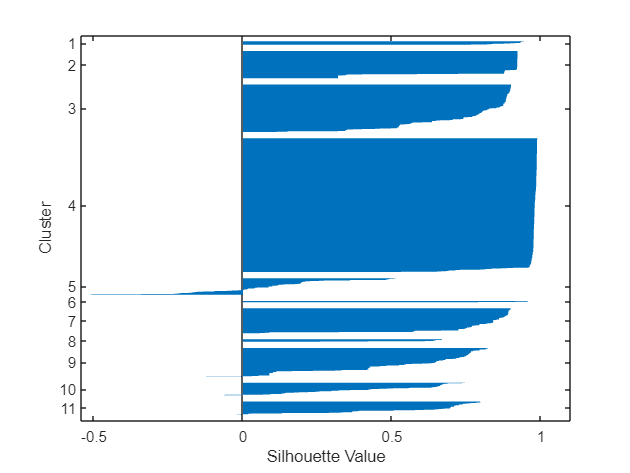

ans = 0.7816

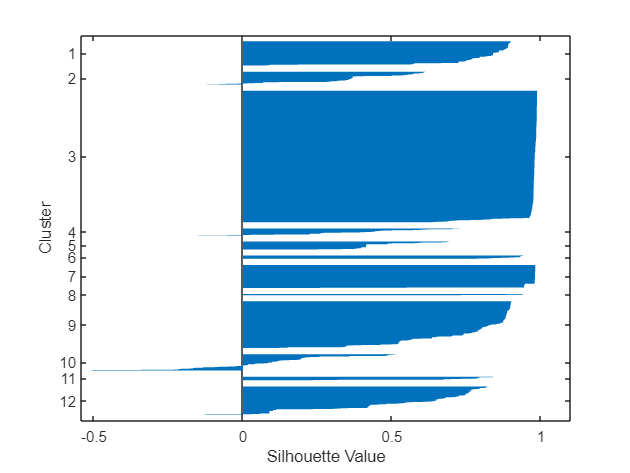

ans = 0.7797


% Perform k-means clustering for each number of clusters on bus_line
for i = 1:length(k_values)
    k = k_values(i);
    
    % Run k-means clustering on bus_line
    [idx_line,centroids, sumd] = kmeans(bus_line, k);
    
    % Calculate total variance
    total_variance = sum(sumd);
    
    % Calculate percentage variance for current number of clusters
    variance_pct_busline(i) = (total_variance - sumd(1)) / total_variance * 100;
    figure;
    sil_scores = silhouette(bus_line,idx_line);
    silhouette(bus_line,idx_line);
    mean(sil_scores)
end

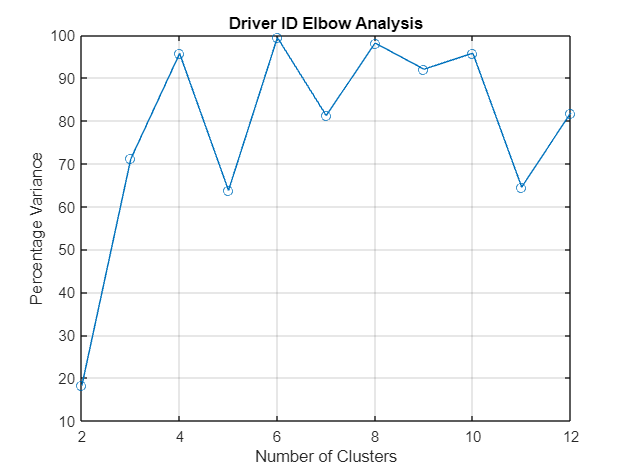


% Plot elbow curves for each matrix separately
figure;
plot(k_values, variance_pct_driver, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Driver ID Elbow Analysis');
grid on;

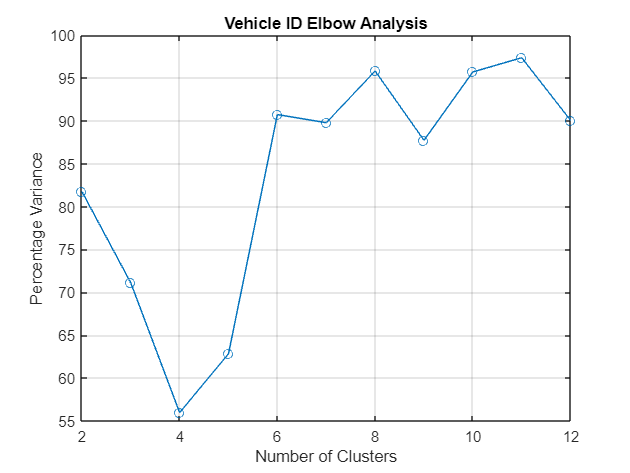


plot(k_values, variance_pct_vehicle, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Vehicle ID Elbow Analysis');
grid on;

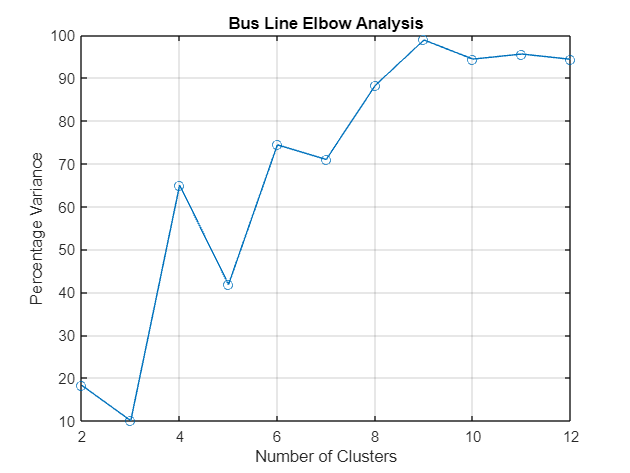


plot(k_values, variance_pct_busline, '-o');
xlabel('Number of Clusters');
ylabel('Percentage Variance');
title('Bus Line Elbow Analysis');
grid on;



idx_line = kmeans(bus_line, 5);
idx_vehicle = kmeans(vehicle_id, 6);
idx_driver = kmeans(driver_id, 5);

% Assign a new ID to each cluster
cluster_line_ids = (1:5)';
cluster_vehicle_ids = (1:6)';
cluster_driver_ids = (1:5)';


% Assign a new ID to each cluster
new_ids_line = cluster_line_ids(idx_line);
new_ids_vehicle = cluster_vehicle_ids(idx_vehicle);
new_ids_driver = cluster_driver_ids(idx_driver);

% Replace the original IDs in the dataset with the new IDs
short_matrix_no_id = [short_matrix_no_id, new_ids_line new_ids_vehicle new_ids_driver];
X = short_matrix_no_id;
X(:, [1,6,8]) = [];
Y = short_matrix_no_id(:,15);
% Split data into training and testing sets
train_ratio = 0.7;
train_size = round(train_ratio*size(X,1));
train_idx = randperm(size(X,1),train_size);
test_idx = setdiff(1:size(X,1),train_idx);
X_train = X(train_idx,:);
Y_train = Y(train_idx,:);
X_test = X(test_idx,:);
Y_test = Y(test_idx,:);

|====================================================================================================================|
| Iter | Eval   | Objective:  | Objective   | BestSoFar   | BestSoFar   |  Activations |  Standardize |       Lambda |
|      | result | log(1+loss) | runtime     | (observed)  | (estim.)    |              |              |              |
|====================================================================================================================|
|    1 | Best   |  2.3689e-05 |      10.345 |  2.3689e-05 |  2.3689e-05 |         tanh |         true |   7.0597e-07 |
|    2 | Accept |  0.00024488 |       2.281 |  2.3689e-05 |  3.0189e-05 |         none |        false |     0.011278 |
|    3 | Accept |  4.5698e-05 |      10.874 |  2.3689e-05 |  2.3829e-05 |         tanh |        false |   7.1469e-07 |
|    4 | Accept |   0.0020269 |     0.57276 |  2.3689e-05 |   0.0005839 |         none |         true |     0.035191 |
|    5 | Accept |    0.049549 |     0.60167 |  2

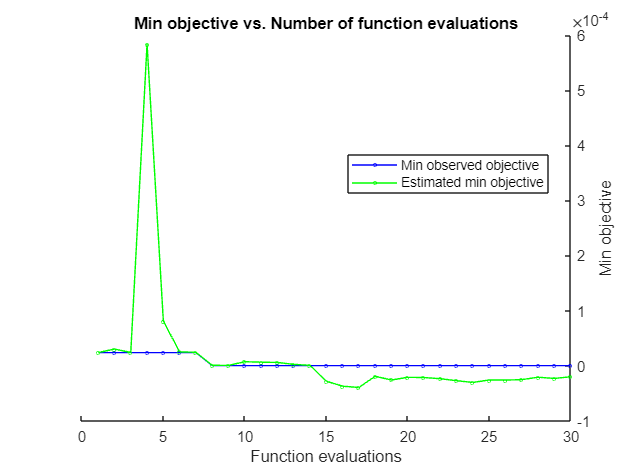


__________________________________________________________
Optimization completed.
MaxObjectiveEvaluations of 30 reached.
Total function evaluations: 30
Total elapsed time: 179.453 seconds
Total objective function evaluation time: 166.1532

Best observed feasible point:
    Activations    Standardize      Lambda  
    ___________    ___________    __________

       none           false       2.2523e-06

Observed objective function value = 3.7345e-09
Estimated objective function value = 1.1708e-05
Function evaluation time = 6.4471

Best estimated feasible point (according to models):
    Activations    Standardize      Lambda  
    ___________    ___________    __________

       none           false       0.00031841

Estimated objective function value = -2.0158e-05
Estimated function

% Train the final model with optimized hyperparameters
net = fitrnet(X_train, Y_train, 'OptimizeHyperparameters', {'Activations', 'Standardize', 'Lambda'}, 'HyperparameterOptimizationOptions', struct('AcquisitionFunctionName', 'expected-improvement-plus'));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%5

% Test neural network
Y_pred = net.predict(X_test);

% Display the covariance matrix and error
covariance_matrix = cov(Y_pred,Y_test);
covariance_matrix

covariance_matrix =     1.0257    1.0259
    1.0259    1.0261


% Calculate the covariance error
cov_error = sum(sum((cov(Y_pred) - Y_test).^2));
disp('Covariance Error: ');

Covariance Error: 


cov_error

cov_error = 6.1678e+03

mse = mean((Y_pred-Y_test).^2)

mse = 2.1865e-07

acc = mean(abs(Y_pred-Y_test)<0.02);
disp(['Accuracy: ' num2str(acc)]);

Accuracy: 1


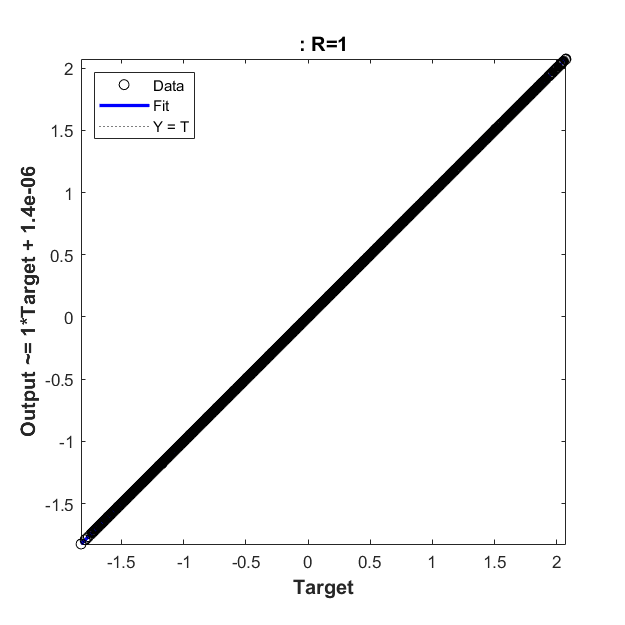

plotregression(Y_pred,Y_test);